## 创建变量

XTrain_pre=TrainingFeatures(1:3500,:);
XTrain=cell(3500,1);
for i=1:3500
    XTrain{i}=cell2mat(XTrain_pre(i)).';
end
YTrain=label_set(1:3500,:);
XTest_pre=TrainingFeatures(3501:5000,:);
XTest=cell(1500,1);
for i=1:1500
    XTest{i}=cell2mat(XTest_pre(i)).';
end
YTest=label_set(3501:5000,:);

## 构建LSTM网络

inputSize = 13;
numHiddenUnits = 128;
numClasses = 5;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

maxEpochs = 100;
miniBatchSize = 27;

options = trainingOptions('adam', ...
    'ExecutionEnvironment','gpu', ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'GradientThreshold',1, ...
    'Verbose',false, ...
    'Plots','training-progress');

## 训练

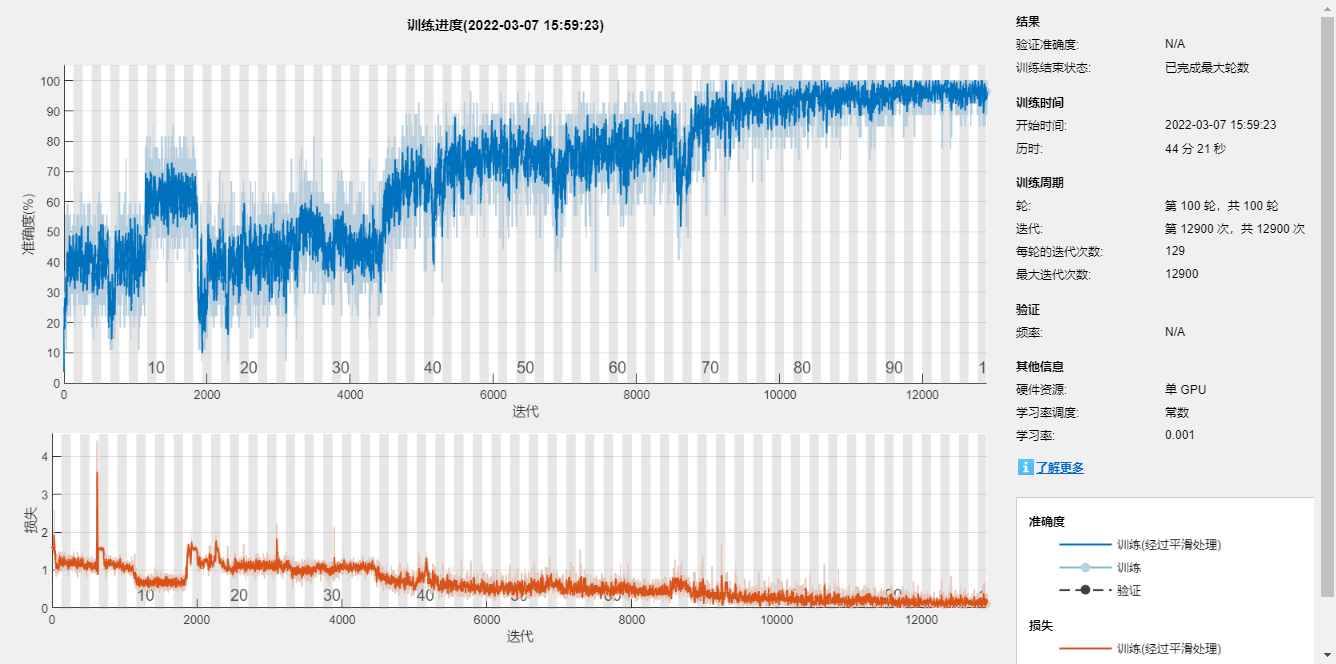

net =   SeriesNetwork - 属性:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'sequenceinput'}
    OutputNames: {'classoutput'}


net=trainNetwork(XTrain,YTrain,layers, options)

## 预测

YPred = classify(net,XTest, ...
    'MiniBatchSize',miniBatchSize, ...
    'SequenceLength','longest')

YPred = 1500×1 categorical 数组
     1 
     3 
     3 
     1 
     2 
     2 
     2 
     0 
     0 
     2 
     3 
     3 
     1 
     1 
     0 
     1 
     3 
     0 
     1 
     0 
     2 
     1 
     0 
     2 
     2 
     4 
     3 
     1 
     3 
     0 


## 精确度检验

acc = sum(YPred == YTest)./numel(YTest)

acc = 0.8847